# Structuring and Manipulating Data

[⇦ Overview](matlab: run("OpenOverview.m"))

A computer stores every bit of data as numbers. It is important to remember this so that you can recognize places where you may need to be clear about what form of data you are using. This script will address several key types of data that you will work with when programming. How can a computer store the irrational number $\pi$? Are there any numbers that humans work with easily that computers struggle with? Why or why not?

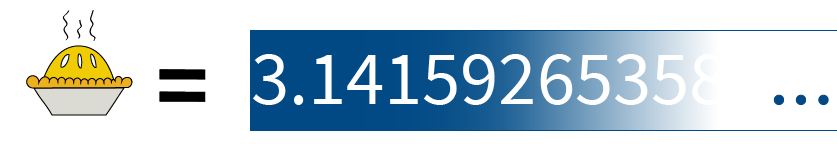

This script will cover basic programming with numbers and text.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build familiarity with MATLAB, as concepts and commands are introduced together, but some familiarity with the Live Editor environment was introduced in [Introduction.mlx](matlab:open('./Introduction.mlx')). 

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running all code blocks.

## Simple Data Structures

The simplest types of data are scalars: data that is a single unit of information such as a number or a phrase. First, consider what happens with numbers.

### Doubles

A *double* is a [floating-point](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) representation of a number. 

   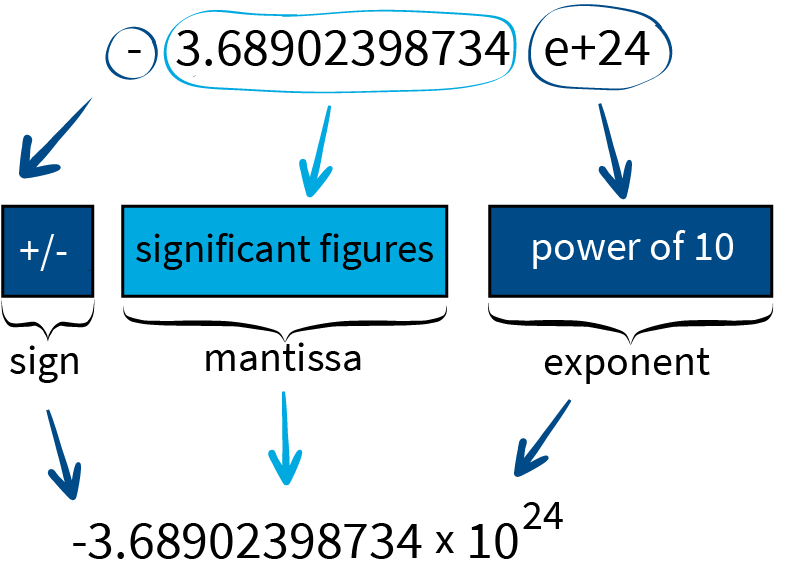

Floating-point numbers use scientific notation to allow the largest possible range of values with a fixed number of digits to work with. Careful consideration, however, will note that there are a finite number of possible combinations of a fixed number of digits and there are an infinite number of possible real numbers in the same range of values no matter what range is chosen to be covered.  

#### Floating point arithmetic

Consider a bit of mathematics. If $a$ is a finite number, then algebraically you can see that 

$\frac{(1000a)}{1000} = 1000\left(\frac{a}{1000}\right) =$$\frac{1000a}{1000} = \left(\frac{1000}{1000}\right)a = a$.

However, if we let $a = 1\times 10^{-321}$ and compute this on the computer we have:

1000*1e-321/1000
1e-321/1000*1000

[Remember](matlab:open('./CollectedProTips.mlx')), you can run this code block by clicking the    **Run Section** button in the **Live Editor** tab.

You might object and say that $1\times 10^{-321}$ is practically $0$ anyway, so let's make this a bit more extreme. Let's say that instead of only `1000` copies of `1e-321` you take `1e308` copies. Then you can multiply the final result by` 1e16`. Similarly, you can first divide and then multiply. What do you get now?

((1e308*1e-321)/1000)*1e16
((1e-321/1000)*1e308)*1e16

Mathematically, these values should be identical, but that is not the case for the computations when performed by the computer because the numbers a computer can represent are different from the numbers a human can represent. Simplifying by hand, the values of both of these computations are 1 when all the numbers are real. Using floating point doubles, the first result is close to 1, but not exactly 1, and the second is farther from 1. You can make it even farther away from the real number result by using larger multiples at the end of the calculation. 

#### Recognizing numbers that might cause problems

On a computer, there are only a finite number of possible numbers so every real number is represented by the closest value in the set of numbers the computer can store. This means small nonzero values fall below the threshold which is recognizably different from 0 and the value will get rounded to 0. With a `double`, that value is on the order of `1e-324`. Once the computer has rounded a value to 0, you have no chance to recover by moving outside of that range because any finite number multiplied by 0 will return 0 and any number of 0's added together will also return 0. 

**Pay attention to magnitude**

This means you must avoid working with values that are particularly large or particularly small whenever possible. If you are working with numbers that are close to zero, you want to multiply before dividing to try to avoid accidentally rounding to 0. If you are working with very large numbers, you want to divide before multiplying to try to avoid accidentally rounding to $\infty$. When adding many values, it is important to start from the values that are smallest in magnitude to avoid accidentally adding 0 through loss of precision.

 **Exercise 0.**

Consider a computer which only saves one significant figure in the mantissa, that is 0-9, and allows one digit for the exponent.

a. What is the result of adding `4+4+10`?

b. What is the result of adding `10+4+4`?

**Additional Examples**

% 4/3 does not have an exact representation as a double
% The value of val should be 0, but it isn't
val = 1-3*(4/3-1)

% In fact, 0.1 does not have an exact representation as a double. 
% With only a few terms the error doesn't build up too much
rawValHalf = 0.5;
sumValHalf = 0.1 + 0.1 + 0.1 + 0.1 + 0.1
rawValHalf - sumValHalf

% However, if we include a few more terms the error becomes apparent for
% some operations
rawValOne = 1;
sumValOne = 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1
rawValOne-sumValOne

#### Limits of Precision

This limitation means that there is an inherent loss of precision when performing digital computations.        

Given the logarithmic scaling of the numbers, this precision varies quite a lot. The smallest error is around `0`. The command `eps(n)` will provide the distance to the next larger floating point number. Mathematically, this would be the interval $n$ to $n+\epsilon$, hence the use of `eps` for epsilon. 

eps(0)
eps(5)
eps(5^100)

 **Reflect**.

- How carefully did we choose the example values in lines 1-4? 

- Why are there no `double` numbers between `5^100` and `5^100+1.5e54`?

- Using `eps(n)`, can you say approximately how many `doubles` are there between `1` and `2`? What values of `n` do you want to check? What is the level of precision of your solution?

** Exercise 1**.

The tolerance is an allowable amount of variation between values such that they are still considered the same. One common example of specified tolerances is in industrial manufacturing, such as creating a standard size ball bearing or resistors with a given resistance. If `abs(x1-x2) < tolerance`, then `x1` and `x2` are considered equivalent. Manufacturing items with smaller tolerances will generally be somewhat more expensive. Given the precision allowed by a double, what are reasonable amounts of precision to expect in the following cases?

a. What is a reasonable tolerance for values between 1 and 100?

b. What is a reasonable tolerance for values between 1e9 and 1e10?

% You can use this code block for calculations if you wish.


### Strings

It is important to be able to clearly communicate with other humans as well as with computers. To do so, we must also be able to use text in computer programs both as data and as output. Computers encode text numerically, just like the photographs. Each programming language has its own syntax for declaring that text is a string. Consider the following:

num = 7.4
str = "7.4"

The command `class` will return the class (or data type) of the argument. In this case, you can see that `num` is a `double` and `str` is a string. 

class(num)
class(str)

#### Concatenation

After defining strings, you may want to put them together into words, phrases or sentences. 

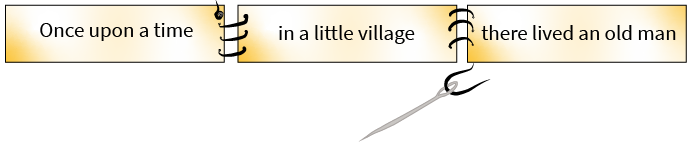

The operation of joining strings is called *concatenation*. In MATLAB, it is possible to concatenate strings using the `+` operator.

str1 = "Turkeys are cute!"
str2 = "Do you like turkeys?"
str1 + str2

Did this work the way you expected? Remember that computers do exactly what you tell them to do. In addition to being extremely detail-oriented regarding spelling and capitalization, you need to remember that spaces (sometimes called whitespace) also have to be represented by numbers for a computer to track them. To make these strings come together normally, you need to include the space somewhere like so:

str1 + " " + str2

or by including an extra space in one of the strings:

"We saw " + num + " turkeys on Thursday!"

Did you see what happened? You can concatenate a `string` with a `double` and the result is a string! This can be very useful for generating human-readable output from a program. Each programming language has its own constraints about how different types of data can interact.  

To split strings into multiple lines of text, you will also need to include "carriage return", from the days of typewriters, or "newline" characters. This can be represented in MATLAB with the `newline` character.

** Exercise 2**.

Concatenate the provided strings and appropriate use of `newline` and `" "` to recreate the following joke in a string named `joke` and a comment explaining what you are doing.

Knock Knock! 

Who's there?

Who! 

Who Who?

I didn't know you were an owl!

str1 = "Knock";
str2 = "Who";
str3 = "'s there";
str4 = "I didn't know you were an owl";
str5 = "!";
str6 = "?";



  **Pro-tip. **In addition to paying attention to whitespace, it is also important to clearly delineate the totality of a single instruction. In the case of this string, the instructions to create `joke` by concatenating so many strings can reach far beyond the limits of a standard line of text. There are two standard ways to approach the problem. The first is to break up a long instruction into a combination of shorter instructions such as

% Excerpt from "The Land of Beyond", by Robert William Service (1874-1958)
poem = "Have ever you heard of the Land of Beyond,"; 
poem = poem + newline + "That dreams at the gates";
poem = poem + " of the day?"

Alternately, you can instruct the computer that multiple lines of code should be treated as a single logical line for purposes of interpreting the meaning, such as

poem = poem + newline + "Alluring it lies at the" + ...
    " skirts of the skies," + newline + "And ever " + ...
    "so far away"

  **Try**. What happens if you delete the ellipses (...) from the code block above? Why? Can you use line breaking in your solution to Exercise 2 to make the code more readable?

### Special Characters

Programming languages also have the need to represent ideas that don't fit as either phrases or numbers. Run the code in this section and consider the results:

a = 2^1024
b = 10^400
c = 2^1024-10^400
d = 0*2^1024
dAlt = (0*2^1020)*2^4

 **Reflect**.

- Do you agree with these answers? How would you express the value of `d`?

- Why do you think `dAlt` evaluates to a different value than `d`? 

- If you accept the proposition that `a = `$\infty$ and that `b = `$\infty$, how would you express the values of `c` and `d`?

#### `Inf`

`Inf` is the symbol that represents the concept of infinity in MATLAB. This could be the value that is the limit of the sequence


$$1,2,3,4,5,6,7,8,9,10,\ldots$$


or it could be the value of 

$\lim_{x \to 0} \frac{1}{x^2}$. 

In the same way that $\infty$ represents numbers that are larger than anything we can count to, `Inf` represents any number which is larger than the largest number the computer can represent. In this case, that is

realmax

Since `Inf` is described by an inequality rather than a precise value, it does not behave the same way as numbers in arithmetic computations. 

#### `NaN`

`NaN` is a symbol that stands for "Not a Number". In math classes you may have encountered the concept of "indefinite forms" such as $\frac{0}{0}$ or $\frac{\infty}{\infty}$ or $0\cdot\infty$. `NaN` is the programming language equivalent that is used to represent any value in a numerical environment that is not a number. 

** Exercise 3**.

What is the smallest integer value of `k` such that `2^k` evaluates to `Inf` in MATLAB? Can you solve this without guess and check? 

% Use this code block for computation related to Exercise 3


## Moving On

You can learn more about numerical and textual classes by reading documentation.

[Numeric Types](https://www.mathworks.com/help/matlab/numeric-types.html)

[Textual Types](https://www.mathworks.com/help/matlab/characters-and-strings.html)

There are many more types of data that are possible, but it is also important to be able to add a bit more structure to the data you are going to ask a computer to manipulate. One standard structure that is quite useful is discussed in [Arrays.mlx](matlab:open('./Arrays.mlx')). 

[⇦ Overview](matlab: run("OpenOverview.m"))